# P & PI Control

Open serial to Pico data port

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Send desired heigth and request for number of samples to Pico

desired_height = 10; 
s.writeline(num2str(desired_height)) % send desired height to Pico

samples = 700;
s.writeline(num2str(samples)) % send number of samples to Pico

height = zeros(1, samples); % create emply row vector for distance collection
voltage = zeros(1, samples); % create emply row vector for voltage collection

% loop for every sample
for i = 1:samples   
    height(i) = s.readline(); % receive distance from serial
    voltage(i) = s.readline(); % receive voltage from serial
end

save r_data2_04_10_2024.mat height voltage

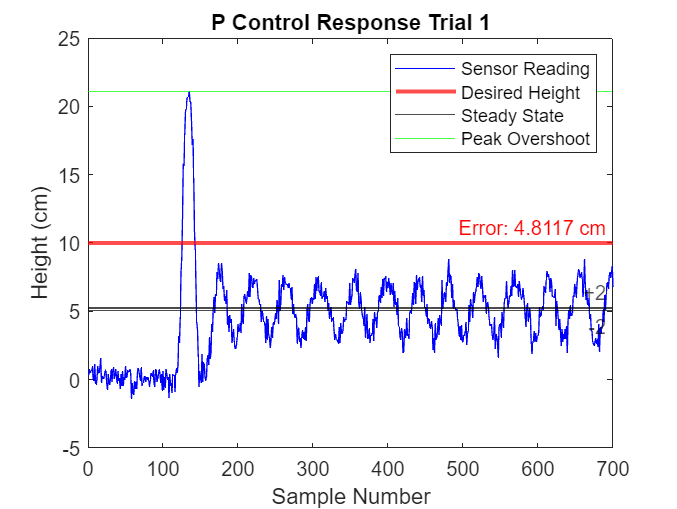

load t_data_04_10_2024.mat

plot(height, "b") % plot height

hold on
ss = mean(height(400:end));
yline(10, "r",'LineWidth', 2) % plot desired height
yline(ss, 'k')
peak = max(height);
yline(peak, 'g')
error = 10 - ss;
pos = max(height(400:end)) + 0.2;
text(690,10.3,"Error: " + error + " cm",'Color','red', ...
    'HorizontalAlignment','right','VerticalAlignment','bottom')
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
hold off
axis([0 700 -5 25]) % set axis limits
title("P Control Response Trial 1")
xlabel("Sample Number")
ylabel("Height (cm)") 
legend("Sensor Reading", "Desired Height", "Steady State", "Peak Overshoot")

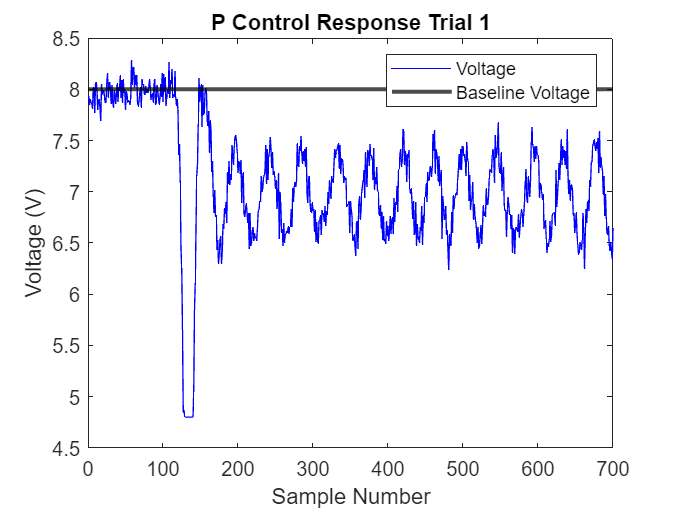


plot(voltage, "b") % plot voltage
hold on
yline(8, 'k', 'LineWidth', 2)
hold off
%axis([0 700 5 7.5])
title("P Control Response Trial 1")
xlabel("Sample Number")
ylabel("Voltage (V)") 
legend("Voltage", "Baseline Voltage")

Calculate linear fit parameters to find baseline voltages

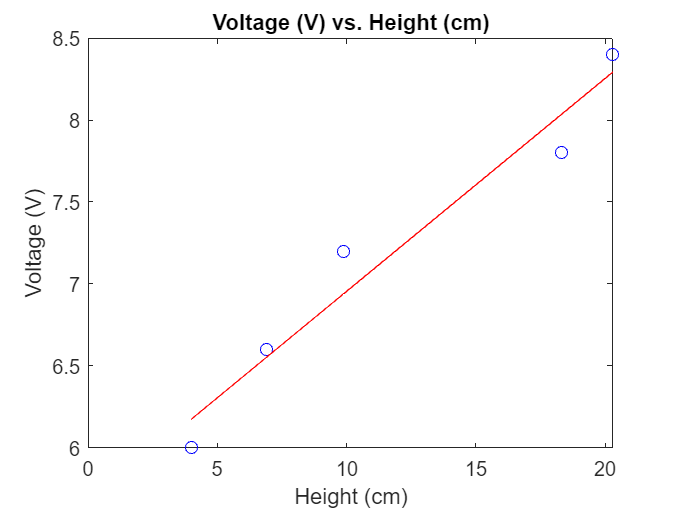

duty_cycle = [50 55 60 65 70]; % expiremented duty cycles
height = [3.99151 6.907516 9.897944 18.32904 20.30173];

voltage = (duty_cycle ./ 100) .* 12; % convert duty_cycle to fan voltage

plot(height, voltage, 'bo') % plot data points

pfit = polyfit(height,voltage,1); % fit line to data 
pval = polyval(pfit, height); % evaluate fitted line

hold on
plot(height, pval, 'r') % plot fitted line
hold off

title("Voltage (V) vs. Height (cm)")
xlabel("Height (cm)")
ylabel("Voltage (V)")


% extract parameters
a = pfit(1)

a = 0.1299

b = pfit(2)

b = 5.6558